# **DERS - 1**

### 1) DEĞİŞKEN TANIMLAMA VE ARİTMETİK İŞLEMLER

#### 1.1) Değişken Tanımlama

a = 4 % Value is shown in the command window.
b = 7; % b is defined here but is redefined below, so it warns us with
% orange underline.
b = 8;
%b = ;% SYNTAX ERROR
name = "Burak";
13;

### 1.2) Aritmetik İşlemler

c = 7 + 21;
d = 12 - 8;
e1 = 5 * 9;
g = 64 / 4;
h = 17 / 5;
i = 2^6;
k = 3 * (23 + 14.7 - 8) / 7.2;
l = 3 == 5;


### 1.3) Hazır Fonksiyonlar (Built-In Functions)

j = 5i;
pi_val = pi;
sqrt_val = sqrt(25);
exp_val = exp(3);
log_val = log10(100);
ln_val = log(exp(1));

#### **ÖRNEK - 1)** $e$ sayısı hazır olarak bulunmadığına göre, kolay kullanım için $e$ sayısı nasıl tanımlanabilir?

e = exp(1);

#### ÖRNEK - 2) Hazır fonksiyonlar arasında `log5(x)` bulunmadığına göre, $\log_{5}25$ değeri nasıl bulunabilir?

log_5_25 = log(25) / log(5);

#### Temel matematiksel fonksiyonlar

sin_val = sin(pi / 2);
cos_val = cos(pi);
tan_val = tan(pi / 4);
arc_sin_val = asin(1) * 180 / pi;
arc_cos_val = acos(-1) * 180 / pi;
arc_tan_val = atan(1) * 180 / pi;
abs_val = abs(-17);
angle_val = angle(1 + 1i) * 180 / pi;
conj_val = conj(1 + 3i);
z = 3 + 5i;
real_z = real(z);
imag_z = imag(z);
fac_val = factorial(4);
comb_val = nchoosek(4, 2);
modulo = mod(5, 3);
ceil_val = ceil(8.2);
floor_val = floor(12.6);
round_val = round(5.8);

### 1.4) Vektörler

prime = [2 3 5 7 11 13];
length_row_vector = length(prime);
size_row_vector = size(prime);

vector = [1, 3, 5, 7, 9];

MATLAB'de vektörlerin indisleri 1'den başlar.

element_at_1 = prime(1);
element_at_4 = prime(4);
prime(6) = 17;
element_at_5 = prime(5); % What do you expect as the result?
prime(3) = 19; % What do you expect as the result?

Eşit aralıklara sahip elemanlardan oluşan bir vektör aşağıdaki gibi oluşturulabilir.

vector2 = 1 : 2 : 12;
vector3 = 2 : 4 : 12;
vector4 = 11 : -2 : 1;
vector5 = 1 : 0.2 : 2;
vector6 = 1 : -2 : 3; % What do you expect as the result?

Eşit aralıklara sahip belli bir eleman sayısından oluşan bir vektör aşağıdaki gibi oluşturulabilir.

vector7 = linspace(-7, 7); % 100 evenly spaced points
vector8 = linspace(-7, 7, 15); % 15 evenly spaced points

Şimdiye kadar gördüğümüz vektörlerin hepsi satır vektördür. Sütun vektörler ise aşağıda verildiği gibi oluşturulabilir.

col_vector1 = [2; 3; 5];

Sütun vektörü, aynı zamanda satır vektörünün **transpozu** alınarak da oluşturulabilir. 

row_vector = [7 12 90];
col_vector2 = transpose(row_vector);
col_vector3 = row_vector.';
col_vector4 = row_vector';

Aynı sayıda elemana sahip olan vektörler aritmetik işlemlere tabi tutulabilirler.

a_vector = [2 4 9 -3 9 -12];
b_vector = [3 7 8 16 -21 4];
addition_vector = a_vector + b_vector;
subtraction_vector = a_vector - b_vector;
%matrix_product = a_vector * b_vector; % What do you expect as the result?

Element bazında (element-wise) çarpma ve bölme işlemleri aşağıda verildiği gibi yapılabilir.

c_vector = [1 2 3 4 5 6];
d_vector = -5 : 2 : 5;
multiplication = c_vector .* d_vector;
division = c_vector ./ d_vector;
power = c_vector.^2;

Vektörler ile kullanılabilecek bazı diğer fonksiyonlar aşağıdaki gibi verilebilir.

a_vectorx2 = 2 * a_vector;
sum_val = sum(a_vector);
prod_val = prod(a_vector);
diff_vector = diff(a_vector);
index = find(a_vector == 9);

Eğer bir hazır fonksiyonun ismini biliyor ama ne yaptığını tam bilmiyor veya hatırlamıyorsarsanız help komutunu kullanabilirsiniz

help sum

**ÖRNEK - 3)** İlk 6 asal sayının karelerinin toplamını bulunuz.

result = sum([2, 3, 5, 7, 11, 13].^2);

MATLAB'in hazır fonksiyonları normal değişkenlere uygulandığı gibi aynen vektörlere de uygulanabilir. Bu durumda fonksiyon vektördeki her elemana ayrı ayrı uygulanarak sonuçta yine bir vektör elde edilir.

angle_vector = 0 : 10 : 90;
rad_vector = angle_vector * pi / 180;
sin_vector = sin(rad_vector);

Vektörlerin istatiksel verileri oldukça önemlidir. Bu veriler, MATLAB'de bulunan hazır fonksiyonlar sayesinde aşağıda verildiği gibi hesaplanabilir.

e_vector = [1 3 5 7 9];
mean_val = mean(e_vector);
var_val = var(e_vector);
min_val = min(e_vector);
max_val = max(e_vector);

### 6) PROBLEM / OLASILIK VE İSTATİSTİK

5 öğrencinin bulunduğu bir "Olasılık ve İstatistik" dersinde 2 vize ve 1 final yapılmaktadır. Buna ek olarak da dönem boyunca 2 ödev verilmektedir. Öğrencilerin ödev, vize ve final notlarını içeren tablo aşağıda verilmiştir:

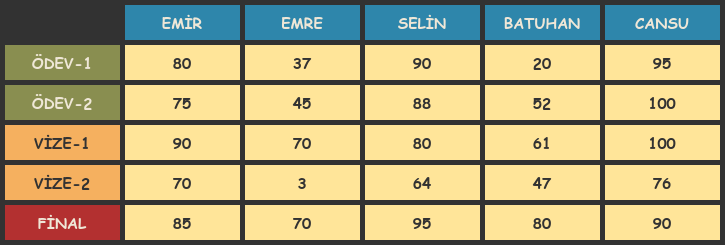

Öğrencinin dersten aldığı ortalama notu belirlemek için ödevlerin her birisinin %5'i, vizelerin her birisinin %25'i ve finalin de %40'ı alınmaktadır.

**1) **Her öğrencinin sonuçlarını farklı bir vektör haline getiriniz.

emir = [80, 75, 90, 70, 85];
emre = [37, 45, 70, 3, 70];
selin = [90, 88, 80, 64, 95];
batuhan = [20, 52, 61, 47, 80];
cansu = [95, 100, 100, 76, 90];

**2) **Her öğrencinin ders ortalama notunu hesaplayarak `avg_vec` isminde yeni bir vektör elde ediniz.

weight_vec = [0.05, 0.05, 0.25, 0.25, 0.4];
avg_vec(1) = sum(emir .* weight_vec);
avg_vec(2) = sum(emre .* weight_vec);
avg_vec(3) = sum(selin .* weight_vec);
avg_vec(4) = sum(batuhan .* weight_vec);
avg_vec(5) = sum(cansu .* weight_vec);

**3) **Sınavların zorluklarını görebilmek adına vizelerin ve finalin ayrı ayrı ortalamalarını bularak `mean_vec` isminde yeni bir vektör elde ediniz.

midterm1 = [emir(3), emre(3), selin(3), batuhan(3), cansu(3)];
midterm2 = [emir(4), emre(4), selin(4), batuhan(4), cansu(4)];
final = [emir(5), emre(5), selin(5), batuhan(5), cansu(5)];

mean_vec(1) = mean(midterm1);
mean_vec(2) = mean(midterm2);
mean_vec(3) = mean(final);

**4) **Emre 2. vizeden aldığı sonucu çok düşük bularak itiraz etmiştir. Bunun sonucunda Emre'nin kağıdını yeniden inceleyen hoca bir soruda hata yaptığını farketmiş ve notu 32 olarak değiştirmiştir. Bu durumda Emre'nin notlarını tutan, her öğrencinin ders ortalama notunu tutan ve vizeler ile finalin ortalama değerlerini tutan vektörleri güncelleyiniz.

emre(4) = 32;
avg_vec(2) = sum(emre .* weight_vec);

midterm2(2) = 32;
mean_vec(2) = mean(midterm2);

**5) **Öğrencilerin ikinci vizeden düşük aldığını gören hoca, 2. vize özelinde çan uygulamaya karar vermiştir. Bunun için en yüksek not alan öğrencinin notu 100'e yükseltilirken diğer öğrencilerin notları da aynı büyüklükte değiştirilmiştir. Bu durumda öğrencilerin notlarını tutan, her öğrencinin ders ortalama notunu tutan ve vizeler ile finalin ortalama değerlerini tutan vektörleri güncelleyiniz.

max_midterm2_point = max(midterm2);
midterm2_diff = 100 - max_midterm2_point;

emir(4) = emir(4) + midterm2_diff;
emre(4) = emre(4) + midterm2_diff;
selin(4) = selin(4) + midterm2_diff;
batuhan(4) = batuhan(4) + midterm2_diff;
cansu(4) = cansu(4) + midterm2_diff;

avg_vec(1) = sum(emir .* weight_vec);
avg_vec(2) = sum(emre .* weight_vec);
avg_vec(3) = sum(selin .* weight_vec);
avg_vec(4) = sum(batuhan .* weight_vec);
avg_vec(5) = sum(cansu .* weight_vec);

mean_vec(2) = mean(midterm2);

**6) **Bu derste alınan tüm notların standart sapmasını aşağıda verilen formülü uygulayarak hesaplayınız ve varyans değerinin kareköküne eşit olduğunu teyit ediniz.


$$\sigma = \sqrt{\frac{1}{N-1} \sum_{i=1}^{N} (x_{i} - m)^{2}}$$


all_notes = [emir emre selin batuhan cansu];
N = length(all_notes);
m = mean(all_notes);
sigma = sqrt(sum((all_notes - m).^2) / (N - 1));
sigma2 = sqrt(var(all_notes));
equality = sigma == sigma2;